yalmip('clear');

%% Parameters
N = 33; T = 24;
S_BASE = 100;     % kVA
V_MIN = 0.95; V_MAX = 1.05;
T_MAX = 10;          % Max Tap position (+/-)
DV = 0.5;           % Tap adjustment (pu)
Tset = -T_MAX:T_MAX;  % Potential tap settings
Tratio = Tset*DV;    % Tap ratios
CB_INJ = 0.15;
CB_OP_LIMIT = 6;
CB_BUNDLE = 6;

% Network topology (parent of each node; 0 = slack)
parent = [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 2 19 20 21 3 23 24 6 26 27 28 29 30 31 32 33];  % Node i's parent
r = [0; 0.01; 0.012; 0.011; 0.01; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.01; 0.012; 0.011; 0.009; 0.01; 0.012; 0.011; 0.01; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.015; 0.017; 0.018;]/10;  % Ohm
x = [0; 0.03; 0.025; 0.02; 0.03; 0.035; 0.03; 0.04; 0.045; 0.033; 0.035; 0.03; 0.04; 0.045; 0.033; 0.03; 0.025; 0.02; 0.03; 0.022; 0.03; 0.025; 0.02; 0.03; 0.035; 0.03; 0.04; 0.045; 0.033; 0.035; 0.03; 0.04; 0.045;]/10;     % Ohm

%% Load Data
base_loads = [0; 50; 120; 110; 0; 45; 30; 0; 25; 20; 0; 15; 20; 30; 0; 25; 0; 0; 20; 15; 20; 0; 50; 0; 0; 120; 0; 110; 0; 0; 45; 0; 15];  % kW
pf = 0.95; theta = acos(pf); tan_phi = tan(theta);

load_profile = [ ...
    0.3 0.3 0.35 0.4 0.5 0.7 0.9 1.1 ...
    1.2 1.25 1.2 1.15 1.1 1.0 0.95 0.9 ...
    0.85 0.75 0.6 0.5 0.45 0.4 0.35 0.3];

% Real and reactive power loads (pu)
P_load = zeros(N, T);
Q_load = zeros(N, T);
for t = 1:T
    P_load(:, t) = base_loads * load_profile(t) / S_BASE;
    Q_load(:, t) = P_load(:, t) * tan_phi;
end

%% YALMIP Variables
P = sdpvar(N, T, 'full');   % Real power flow
Q = sdpvar(N, T, 'full');   % Reactive power flow
v = sdpvar(N, T, 'full');   % Squared voltage
I2 = sdpvar(N, T, 'full');  % Squared current
Tpos = sdpvar(T);           % Tap Positions
d = binvar(length(Tset), T, 'full'); % Tap Decision Matrix
Qcb = sdpvar(3, T, 'full'); % CB Reactive Power
c = binvar(3, CB_BUNDLE, T, 'full');   % CB Controls
b = binvar(3, CB_BUNDLE, T, 'full');

%% Objective: Minimize total line losses
obj = 0;
for t = 1:T
    for i = 2:N
        obj = obj + r(i) * I2(i, t);
    end
end

%% Constraints
constraints = [];
for t = 1:T
    constraints = [constraints, v(1,t) == 1];  % Slack bus voltage
    cbi = 1;
    for i = 2:N
        k = parent(i);

        % Power balance equations
        if(i == 3 || i == 12 || i == 15)
            constraints = [constraints, ...
                P(i,t) == P(k,t) - P_load(i,t) - r(i)*I2(i,t), ...
                Q(i,t) == Q(k,t) + Qcb(cbi, t) - Q_load(i,t) - x(i)*I2(i,t)];
            cbi = cbi+1;
        else
            constraints = [constraints, ...
                P(i,t) == P(k,t) - P_load(i,t) - r(i)*I2(i,t), ...
                Q(i,t) == Q(k,t) - Q_load(i,t) - x(i)*I2(i,t)];
        end
        % Voltage drop (DistFlow)
        if i ~= 2
        constraints = [constraints, ...
            v(i,t) == v(k,t) ...
                     - 2*(r(i)*P(i,t) + x(i)*Q(i,t)) ...
                     + (r(i)^2 + x(i)^2)*I2(i,t)];
        end
        % Current limit approximation (SOCP relaxation)
        constraints = [constraints, ...
            P(i,t)^2 + Q(i,t)^2 <= I2(i,t) * v(k,t)];
    end
    
    % OLTC Constraints
    constraints = [constraints, v(2, t) == (1 + Tset).^2*d(:,t)];
    constraints = [constraints, Tpos(t) == Tset*d(:,t)];
    constraints = [constraints, sum(d(:,t)) == 1];
    % Voltage magnitude limits
    constraints = [constraints, V_MIN^2 <= v(:,t) <= V_MAX^2];
    
    % CB Constraints
    
    for l = 1:3
        for j = 1:CB_BUNDLE
            if (t ~= T)
            constraints = [constraints, ...
                b(l, j, t) == c(l, j, t) + c(l, j, t+1) - 2*(c(l, j, t)*c(l, j, t+1)), ...
                (c(l, j, t)*c(l, j, t+1)) <= c(l, j, t), ...
                (c(l, j, t)*c(l, j, t+1)) <= c(l, j, t+1), ...
                (c(l, j, t)*c(l, j, t+1)) + 1 >= c(l, j, t) + c(l, j, t+1)];
            end
        end
        constraints = [constraints, Qcb(l, t) == sum(c(l, :, t))*CB_INJ];
    end

end
for l = 1:3
    for j = 1:CB_BUNDLE
        constraints = [constraints, sum(sum(b(l,j))) <= CB_OP_LIMIT];
    end
end

%% Solve
ops = sdpsettings('solver','gurobi','verbose',1);
sol = optimize(constraints, obj, ops);

Set parameter Username
Set parameter LicenseID to value 2660695
Set parameter NonConvex to value 2
Academic license - for non-commercial use only - expires 2026-05-05
Gurobi Optimizer version 12.0.1 build v12.0.1rc0 (win64 - Windows 11.0 (26100.2))

CPU model: Intel(R) Core(TM) Ultra 9 185H, instruction set [SSE2|AVX|AVX2]
Thread count: 16 physical cores, 22 logical processors, using up to 22 threads

Non-default parameters:
LogToConsole  0
NonConvex  2

Optimize a model with 4050 rows, 4590 columns and 12042 nonzeros
Model fingerprint: 0x76d216f9
Model has 2424 quadratic constraints
Variable types: 3240 continuous, 1350 integer (1350 binary)
Coefficient statistics:
  Matrix range     [5e-06, 1e+02]
  QMatrix range    [1e+00, 2e+00]
  QLMatrix range   [1e+00, 1e+00]
  Objective range  [9e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e-02, 6e+00]
  QRHS range       [1e+00, 1e+00]
Presolve removed 3957 rows and 4460 columns
Presolve time: 1.90s
Presolved: 221 rows, 2


%% Results
if sol.problem == 0
    disp('Optimization successful');
    v_opt = value(v);
    losses = value(obj);
    currents = value(I2);
    CBs = value(Qcb);
    taps = value(d);
    fprintf('Total losses: %.4f pu\n', losses);
    disp(currents)
    disp(taps)
    disp(v_opt)
    disp(CBs)
else
    disp('Problem with optimization:');
    sol.info
end

Optimization successful


Total losses: 1.8324 pu


       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0243    1.0243    1.3912    1.8143    2.8401    5.5781    9.2362   13.9170   16.6177   18.0688   16.6177   15.2452   13.9170   11.4600   10.3117    9.2362    8.2252    6.4113    4.1008    2.8401    2.3050    1.8143    1.3912    1.0246
    0.4828    0.4828    0.6651    0.8505    1.3389    2.6166    4.2706    6.3592    7.5257    8.1604    7.5257    6.9450    6.3592    5.2713    4.7550    4.2706    3.8130    2.9766    1.9145    1.3389    1.0746    0.8505    0.6651    0.4830
    0.1215    0.1215    0.1698    0.2117    0.3362    0.6555    1.0550    1.5669    1.8440    1.9986    1.8440    1.7102    1.5669    1.3024    1.1741    1.0550    0.9429    0.7380    0.4771    0.3362    0.2669    0.2117    0.1698    0.1216
    0.1214    0.1214    0.1697    0.

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9972    0.9972    0.9967    0.9963    0.9954    0.9936    0.9919    0.9902    0.9895    0.9890    0.9895    0.9898    0.9902    0.9911    0.9915    0.9919    0.9924    0.9932    0.9945    0.9954    0.9959    0.9963    0.9967    0.9972
    0.9960    0.9960    0.9952    0.9947    0.9933    0.9907    0.9884    0.9860    0.9849    0.9843    0.9849    0.9854    0.9860    0.9872    0.9878    0.9884    0.9890    0.9902    0.9921    0.9933    0.9941    0.9947    0.9952    0.9959
    0.9945    0.9945    0.9934    0.

    0.3000    0.3000    0.4500    0.4500    0.6000    0.7500    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.7500    0.6000    0.6000    0.4500    0.4500    0.4500    0.3000
         0         0         0         0         0         0    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500         0         0         0         0         0         0
         0         0         0    0.1500    0.1500    0.1500    0.1500    0.1500    0.3000    0.3000    0.3000    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500         0    0.1500    0.1500    0.1500    0.1500         0         0



b_val = value(b);
disp(b_val)


(:,:,1) =

     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


(:,:,2) =

     0     1     1     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0


(:,:,3) =

     0     0     1     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     1


(:,:,4) =

     0     0     0     0     1     0
     0     0     0     0     0     0
     0     0     0     0     0     0


(:,:,5) =

     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0


(:,:,6) =

     1     0     0     0     0     0
     0     0     0     0     1     0
     0     0     0     0     0     0


(:,:,7) =

     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


(:,:,8) =

     0     0     0     0     0     0
     1     0     0     0     1     0
     1     0     0     0     0     0


(:,:,9)

for l = 1:3
    for j = 1:CB_BUNDLE
        sum(sum(sum(b_val(l,j,1:T-1))))
    end
end

ans = 2

ans = 2

ans = 3

ans = 1

ans = 3

ans = 3

ans = 4

ans = 0

ans = 0

ans = 0

ans = 4

ans = 2

ans = 2

ans = 0

ans = 0

ans = 2

ans = 0

ans = 4

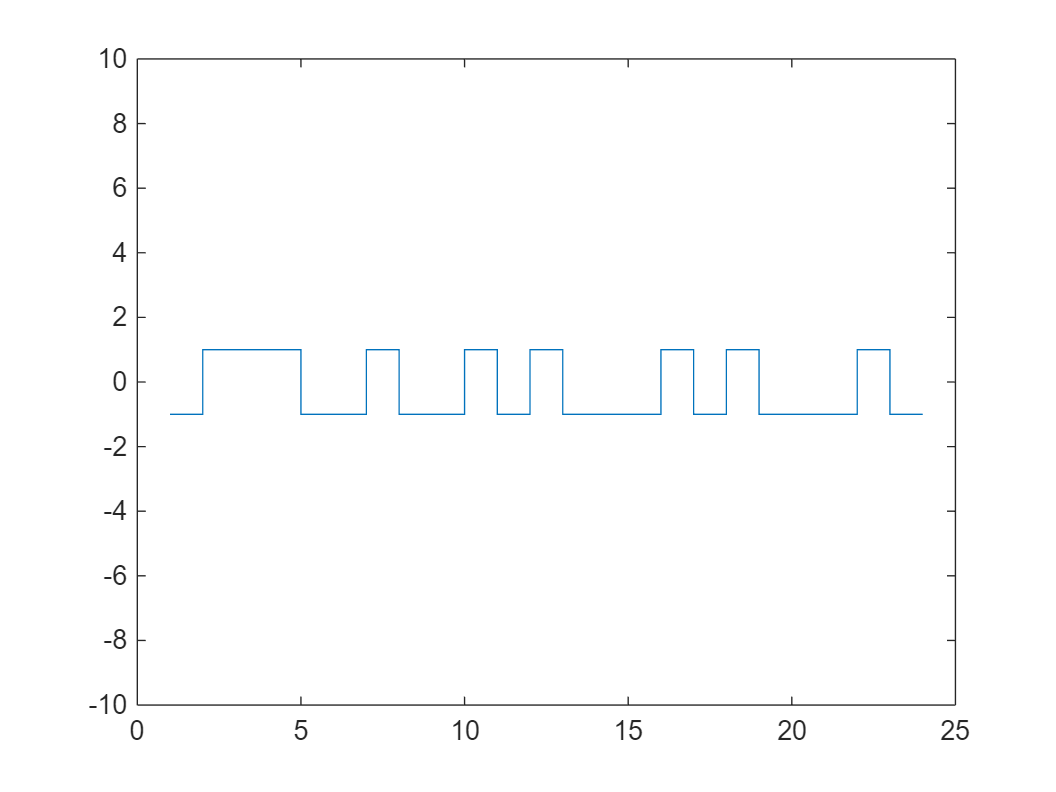

OLTC_ctrl = [];
for i = 1:T
    OLTC_ctrl(i) = find(taps(:,i))-T_MAX;
end

stairs(OLTC_ctrl)


stairs(CBs(1,1:T-1))
hold on
stairs(CBs(2,1:T-1))
stairs(CBs(3,1:T-1))
legend("CB1", "CB2", "CB3")
ylim([0, 1]);
hold off